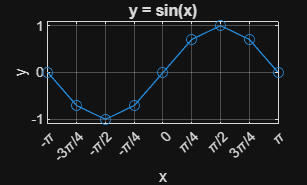

% Name: Augustas
% Surname: Padegimas
% Group: EDIfu-25/2
% Laboratory work: 2
% Variant: 6
% Date: 2026-09-21

% Mandatory task
%% TASK 1 - 2D GRAPHS

% Task 1a
x = -pi:pi/4:pi;
y = sin(x);

figure;

plot(x, y, 'o-');
grid on;

title('y = sin(x)');
xlabel('x');
ylabel('y');

xticks([-pi -3*pi/4 -pi/2 -pi/4 0 pi/4 pi/2 3*pi/4 pi]);
xticklabels({'-\pi','-3\pi/4','-\pi/2','-\pi/4','0',...
    '\pi/4','\pi/2','3\pi/4','\pi'});

xlim([-pi pi]);
ylim([-1.1 1.1]);

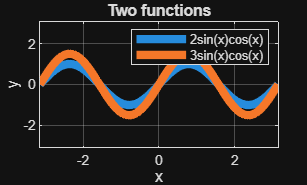



% Task 1b
x = -pi:pi/100:pi;

y1 = 2*sin(x).*cos(x);
y2 = 3*sin(x).*cos(x);

figure;

plot(x, y1, 'LineWidth', 5);
hold on;
plot(x, y2, 'LineWidth', 5);
hold off;

grid on;

title('Two functions');
xlabel('x');
ylabel('y');

legend('2sin(x)cos(x)', '3sin(x)cos(x)');

xlim([-pi pi]);
ylim([-3.1 3.1]);

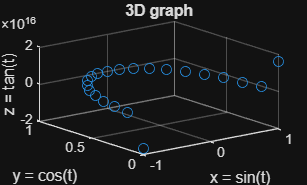



%% TASK 2 - 3D GRAPH

t = -pi/2:pi/20:pi/2;

x = sin(t);
y = cos(t);
z = tan(t);

figure;

plot3(x, y, z, 'o');

grid on;

title('3D graph');
xlabel('x = sin(t)');
ylabel('y = cos(t)');
zlabel('z = tan(t)');



%% COMPLEMENTARY TASK

A = 7;
f = 9;
sigma = 1.2;

U1 = 4.5;
U2 = 2.5;

t = 0:0.002:1;

% Create the original signal
s = A*cos(2*pi*f*t);

% Add random noise
n = sigma*randn(size(t));

% Signal affected by noise
originalSignal = s + n;

% Filter the signal
filteredSignal = originalSignal;

% Replace values with absolute value lower than U2 with zero
filteredSignal(abs(filteredSignal) < U2) = 0;


% Find samples which exceed U1
samplesAboveU1 = originalSignal(originalSignal > U1);

% Number of samples in original signal
numberOfSamples = length(originalSignal);

% Number of samples above U1
numberAboveU1 = length(samplesAboveU1);

% Minimum and maximum values of filtered signal
minimumValue = min(filteredSignal);
maximumValue = max(filteredSignal);


% Display results
disp(' ');

disp('--- SIGNAL RESULTS ---');

--- SIGNAL RESULTS ---


disp(['Number of samples: ', num2str(numberOfSamples)]);

Number of samples: 501


disp(['Number of samples above U1: ', num2str(numberAboveU1)]);

Number of samples above U1: 138


disp(['Minimum filtered voltage: ', num2str(minimumValue), ' V']);

Minimum filtered voltage: -9.6295 V


disp(['Maximum filtered voltage: ', num2str(maximumValue), ' V']);

Maximum filtered voltage: 8.9168 V


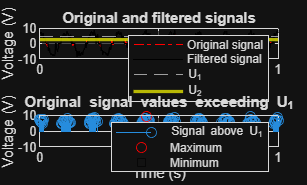




figure;


subplot(2,1,1);

plot(t, originalSignal, 'r-.');
hold on;

plot(t, filteredSignal, 'k-');

yline(U1, '--');
yline(U2, '-y', 'LineWidth', 2);

hold off;

grid on;

title('Original and filtered signals');
xlabel('Time (s)');
ylabel('Voltage (V)');

legend('Original signal', 'Filtered signal', 'U_1', 'U_2');

xlim([min(t) max(t)]);


subplot(2,1,2);

signalAboveU1 = originalSignal;
signalAboveU1(originalSignal <= U1) = NaN;

stem(t, signalAboveU1);

hold on;

maxValue = max(originalSignal);
minValue = min(originalSignal);

maxPositions = find(originalSignal == maxValue);
minPositions = find(originalSignal == minValue);

plot(t(maxPositions), originalSignal(maxPositions), 'ro');

plot(t(minPositions), originalSignal(minPositions), 'ks');

hold off;

grid on;

title('Original signal values exceeding U_1');
xlabel('Time (s)');
ylabel('Voltage (V)');

legend('Signal above U_1', 'Maximum', 'Minimum');

xlim([min(t) max(t)]);